clc; clear; close all;


% Parameters
l_B = 0.25/2;
l_P = 0.25/2;
I_B = 2*(1/12)*0.05*0.25^2;
I_P = (1/12)*0.05*0.25^2;
L = 1.3/1000;
R = 4.2;
m_P = 0.05;
B_B = 100;%0.001;
B_P = 0.001;
g = 9.81;
K_t = 0.047;
K_e = 0.048;

% For Runge Kutta solver
tspan = [0 5];
x0 = [
    -pi/2;
    0;
    0;
    0;
    0];

% Creating function handler for function, this setts the parameters.
odeFunHandler = @(t, x) odeFun(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e)

odeFunHandler = function_handle with value:
    @(t,x)odeFun(x,l_B,l_P,I_B,I_P,L,m_P,B_B,B_P,R,g,K_t,K_e)


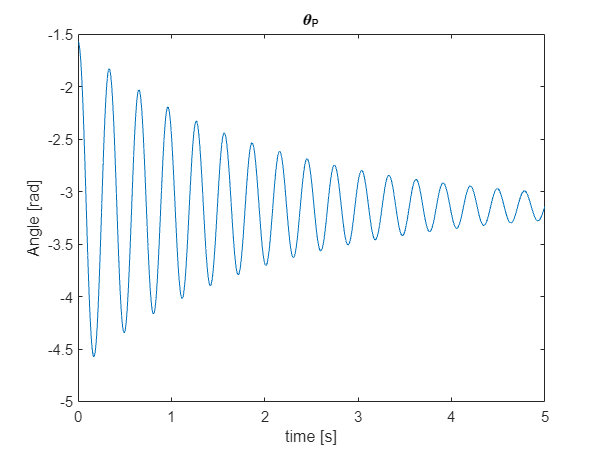


% Rungta Kutta solver
[t, x] = ode45(odeFunHandler, tspan, x0);


% Plotting:
plot(t, x(:, 1));
title('\theta_P');
ylabel('Angle [rad]');
xlabel('time [s]');

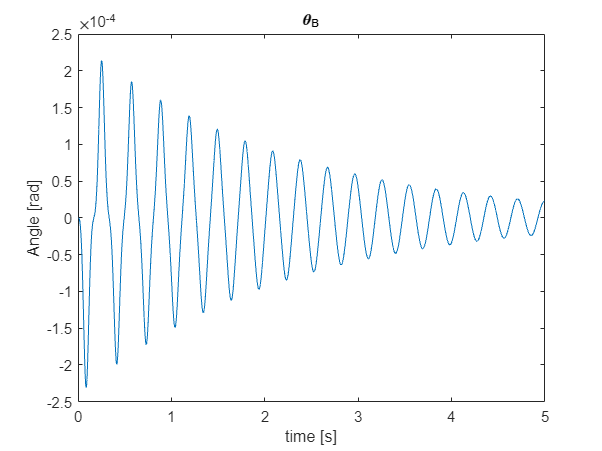


plot(t, x(:, 3))
title('\theta_B')
ylabel('Angle [rad]');
xlabel('time [s]');

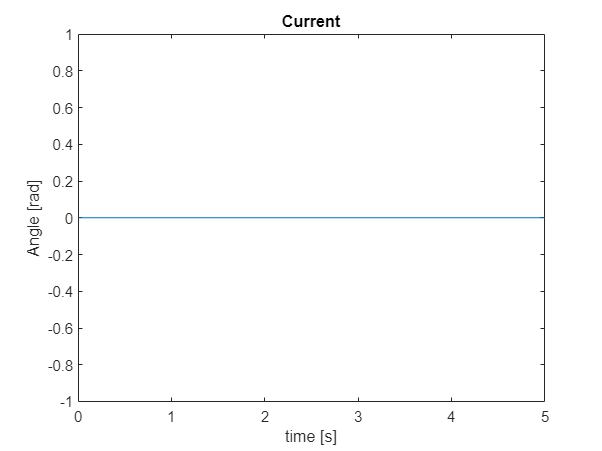


plot(t, x(:, 5))
title('Current')
ylabel('Angle [rad]');
xlabel('time [s]');

function dxdt = odeFun(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e)
dxdt = [
    x(2); 
    -(g*m_P*sin(x(1)) - B_P*x(2) + l_P^2*m_P*cos(x(1))*sin(x(1))*x(4)^2 + (l_B*l_P*m_P*cos(x(1))*(m_P*sin(2*x(1))*x(4)*l_P^2*x(2) - l_B*m_P*sin(x(1))*l_P*x(2)^2 + B_B*x(4) - K_t*x(5)))/(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B))/((m_P*l_P^2 + I_P)*((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1));
    x(4);
    (B_B*x(4) - K_t*x(5) + l_P^2*m_P*sin(2*x(1))*x(4)*x(2) - l_B*l_P*m_P*sin(x(1))*x(2)^2 + (l_B*l_P*m_P*cos(x(1))*(m_P*cos(x(1))*sin(x(1))*l_P^2*x(4)^2 - B_P*x(2) + g*m_P*sin(x(1))))/(m_P*l_P^2 + I_P))/(((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B));
    -(K_e*x(4) - 0 + R*x(5))/L %U
    ];
dxdt(5) = 0;
end